clc;clear;close all;
addpath(genpath('C:\Users\liou-\OneDrive - Danmarks Tekniske Universitet\Elektrotekniologi - Master\2. semester\34746 Robust and fault-tolerant control\L01\SA Tool\SaTool_3_0100\sa_tool_3_0100')) % add path to sa_tools

% Inputs
syms u1(t) u2(t)

ST_input(1,:) = {u1,u2}; % symbolic variable
ST_input(2,:) = {'u_1\\left(t\\right)','u_2\\left(t\\right)'}; % LaTeX expression


% Measurements
syms y1(t) y2(t) y3(t) % Symbolic measurement declearation
ST_meas(1,:) = {y1, y2, y3}; % symbolic variable
ST_meas(2,:) = {'y\\left(t\\right)','y_2','y_3'}; % LaTeX expression

% Unknowns
syms  th1(t) th2(t) th3(t) th1d(t) th2d(t) th3d(t) w1(t) w2(t) w3(t) w1d(t) w2d(t) w3d(t) d(t)
ST_unknowns(1,:) = {...
    th1, th2, th3, ...
    th1d, th2d, th3d, ...
    w1, w2, w3, ...
    w1d, w2d, w3d, ...
    d}; % symbolic variable

ST_unknowns(2,:) = {'th_1','th_2','th_3',...
    'th_1d','th_2d','th_3d',...
    'w_1','w_2','w_3',...
    'w_1d','w_2d','w_3d',...
    'd'}; % LaTeX expression

% Parameter
syms J1 J2 J3 k1 k2 b1 b2 b3

ST_parameters(1,:) = {J1, J2, J3, k1, k2, b1, b2, b3}; % symbolic variable
ST_parameters(2,:) = {'J_1','J_2','J_3','k_1','k_2','b_1','b_2','b_3'}; % LaTeX expression

ST_cons(1,:) = {'c1','c2','c3','c4','c5','c6','d7','d8','d9','d10','d11','d12','m13','m14','m15'};
ST_cons(2,:) = {'c_1','c_2','c_3','c_4','c_5','c_6','d_7','d_8','d_9','d_{10}','d_{11}','d_{12}','m_{13}','m_{14}','m_{15}'};   % LaTeX
ST_cons(3,:) = {...
    0 == th1d - w1, ...
    0 == J1*w1d - u1 + b1*w1 + k1*(th1-th2)+d, ...
    0 == th2d - w2, ...
    0 == J2*w2d - u2 + b2*w2 + k1*(th2-th1)+ k2*(th2-th3), ...
    0 == th3d - w3, ...
    0 == J3*w3d + b3*w3 + k2*(th3-th2),...
    0 == th1d - diff(th1,t),...
    0 == w1d - diff(w1,t),...
    0 == th2d - diff(th2,t),...
    0 == w2d - diff(w2,t),...
    0 == th3d - diff(th3,t),...
    0 == w3d - diff(w3,t),...
    0 == y1 - th1,...
    0 == y2 - th2,...
    0 == y3 - th3};

canfail = [2, 4, 6, 13, 14, 15]; 
domains  = ones(1,length(ST_cons(1,:)));

% map the states in the derivative constraints
cons_oneway = {...
    [], ...      % c1
    [], ...      % c2
    [], ...      % c3
    [], ...      % c4
    [], ...      % c5
    [], ...      % c6
    {th1}, ...   % d7
    {w1}, ...    % d8
    {th2}, ...   % d9
    {w2}, ...    % d10
    {th3}, ...   % d11
    {w3}, ...    % d12
    [], ...      % m13
    [], ...      % m14
    []};         % m15




ST_IncMat = sa_incidencematrix(ST_cons,ST_input,ST_meas,ST_unknowns,cons_oneway);


ST_sys =...
    sa_create(ST_IncMat,ST_cons,...
    ST_input, ST_meas,ST_unknowns,...
    domains, canfail,ST_parameters);

ST_sys=sa_match(ST_sys,'rank');

sa_disp(ST_sys)


sa_report(ST_sys,'assignment1','pdf','analytic_expressions',true);
winopen('assignment1.pdf');


sa_disp(ST_sys,'t');  % matching

disp('Parity relation symbolic form:')
sa_disp(ST_sys,'s');  % symbolic parity

  % d10(c3(d9(m14(y2))),c4(u2,m13(y1),m14(y2),m15(y3),c3(d9(m14(y2)))))
  % d12(c5(d11(m15(y3))),c6(m14(y2),m15(y3),c5(d11(m15(y3)))))

disp('Parity relation analytic form:')
sa_disp(ST_sys,'a');  % analytic parity

%  0 == (u2(t) - b2*diff(y2(t), t) + k1*y1(t) - k1*y2(t) - k2*y2(t) + k2*y3(t))/J2 - diff(y2(t), t, t)
%  0 == (k2*(y2(t) - y3(t)) - b3*diff(y3(t), t))/J3 - diff(y3(t), t, t)




clear variables; clc; close all;

syms u1 u2 y1 y2 y3
syms J1 J2 J3 k1 k2 b1 b2 b3 s

% laplace
r1 = (u2 - b2*s*y2 + k1*y1 - k1*y2 - k2*y2 + k2*y3)/J2 - s^2*y2

$$r1 = \frac{u_{2}+k_{1}\,y_{1}-k_{1}\,y_{2}-k_{2}\,y_{2}+k_{2}\,y_{3}-b_{2}\,s\,y_{2}}{J_{2}}-s^{2}\,y_{2}$$

r2 = (k2*(y2 - y3) - b3*s*y3)/J3 - s^2*y3;


r1_collected = collect(r1,[y1,y2,y3,u1,u2])

$$r1\_collected = \frac{k_{1}}{J_{2}}\,y_{1}+\left(-\frac{k_{1}+k_{2}+b_{2}\,s}{J_{2}}-s^{2}\right)\,y_{2}+\frac{k_{2}}{J_{2}}\,y_{3}+\frac{u_{2}}{J_{2}}$$

r2_collected = collect(r2,[y1,y2,y3,u1,u2])

$$r2\_collected = \frac{k_{2}}{J_{3}}\,y_{2}+\left(-\frac{k_{2}+b_{3}\,s}{J_{3}}-s^{2}\right)\,y_{3}$$


IO = [u1; u2; y1; y2; y3];

G=jacobian([r1_collected;r2_collected],IO);
G=simplify(G);


## Transfer function

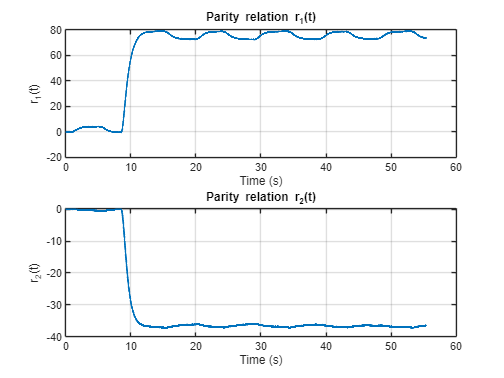

s = tf('s');
Ts = 0.04;

% parameter
J1 = 0.0025;
J2 = 0.0018;
J3 = 0.0018;
k1 = 2.7;
k2 = 2.6;
b1 = 0.0029;
b2 = 0.0002;
b3 = 0.00015;

wn1 = 2;
Q1 = wn1^2/(s^2+2*wn1*s+wn1^2);

wn2 = 2;
Q2 = wn2^2/(s^2+2*wn2*s+wn2^2);

G_r1_u2 = minreal(1/J2*Q1);
G_r1_y1 = minreal(k1/J2*Q1);
G_r1_y2 = minreal((-(k1+k2+b2*s)/J2-s^2)*Q1);
G_r1_y3 = minreal(k2/J2*Q1);

G_r2_y2 = minreal(k2/J3*Q2);
G_r2_y3 = minreal((-(k2+b3*s)/J3-s^2)*Q2);

G_mimo = [ 0, G_r1_u2, G_r1_y1, G_r1_y2, G_r1_y3; 
           0, 0,       0,       G_r2_y2, G_r2_y3 ];

Gd_mimo = minreal(c2d(G_mimo, Ts, 'tustin'));

% Discrete tf models
% G_r1
Gd_r1_u2 = Gd_mimo(1,2);
Gd_r1_y1 = Gd_mimo(1,3);
Gd_r1_y2 = Gd_mimo(1,4);
Gd_r1_y3 = Gd_mimo(1,5);
Gd_r2_y2 = Gd_mimo(2,4);
Gd_r2_y3 = Gd_mimo(2,5);

% num den for r1
[num_r1_u2, den_r1_u2] = tfdata(Gd_r1_u2,'v');
[num_r1_y1, den_r1_y1] = tfdata(Gd_r1_y1,'v');
[num_r1_y2, den_r1_y2] = tfdata(Gd_r1_y2,'v');
[num_r1_y3, den_r1_y3] = tfdata(Gd_r1_y3,'v');

% num den for r2
[num_r2_y2, den_r2_y2] = tfdata(Gd_r2_y2,'v');
[num_r2_y3, den_r2_y3] = tfdata(Gd_r2_y3,'v');

% Q3

data = load('ECP502Data.mat');
% imported are
% t u1 u2 y_meas

t = data.t(:);
u1 = data.u_1(:);
u2 = data.u_2(:);
y1 = data.y_meas(:,1);
y2 = data.y_meas(:,2);
y3 = data.y_meas(:,3);

r1_sim =    lsim(G_r1_u2,u2,t) + ...
            lsim(G_r1_y1,y1,t) + ...
            lsim(G_r1_y2,y2,t) + ...
            lsim(G_r1_y3,y3,t);

r2_sim =    lsim(G_r2_y2,y2,t) + ...
            lsim(G_r2_y3,y3,t);

% plot of input and output data
% figure;
% subplot(5,1,1)
% plot(t,u1,'LineWidth',1.5); hold on; grid on;
% xlabel('Time (s)'); ylabel('u_1(t)'); title('Input u_1(t)');
% subplot(5,1,2)
% plot(t,u2,'LineWidth',1.5); hold on; grid on;
% xlabel('Time (s)'); ylabel('u_2(t)'); title('Input u_2(t)');
% subplot(5,1,3)
% plot(t,y1,'LineWidth',1.5); hold on; grid on;
% xlabel('Time (s)'); ylabel('y_1(t)'); title('Measurement y_1(t)');
% subplot(5,1,4)
% plot(t,y2,'LineWidth',1.5); hold on; grid on;
% xlabel('Time (s)'); ylabel('y_2(t)'); title('Measurement y_2(t)');
% subplot(5,1,5)
% plot(t,y3,'LineWidth',1.5); hold on; grid on;
% xlabel('Time (s)'); ylabel('y_3(t)'); title('Measurement y_3(t)');

% plot of parity relation with data
figure; 
subplot(2,1,1)
plot(t,r1_sim,'LineWidth',1.5); hold on; grid on;
xlabel('Time (s)'); ylabel('r_1(t)'); title('Parity relation r_1(t)');
subplot(2,1,2)
plot(t,r2_sim,'LineWidth',1.5); hold on; grid on;
xlabel('Time (s)'); ylabel('r_2(t)'); title('Parity relation r_2(t)');



% input y2 isn't working / faulty as we should expect 

% Q4

% clear; clear all;

syms u1 u2
% syms y1 y2 y3
syms  th1 th2 th3 th1d th2d th3d w1 w2 w3 w1d w2d w3d d
syms f_u1 f_u2 f_y1 f_y2 f_y3
syms J1 J2 J3 k1 k2 b1 b2 b3 real
syms s tau real

% parameter
% J1 = 0.0025;
% J2 = 0.0018;
% J3 = 0.0018;
% k1 = 2.7;
% k2 = 2.6;
% b1 = 0.0029;
% b2 = 0.0002;
% b3 = 0.00015;

x = [th1; th2; th3; w1; w2; w3];

u = [u1; u2];

% d = d;

f = [f_u1,f_u2,f_y1,f_y2,f_y3];

solve(0 == J1*w1d - u1 + b1*w1 + k1*(th1-th2)+d,w1d);
solve(0 == J2*w2d - u2 + b2*w2 + k1*(th2-th1)+ k2*(th2-th3),w2d);
solve(0 == J3*w3d + b3*w3 + k2*(th3-th2),w3d);

th1d = w1;
w1d = -(d - u1 + b1*w1 + k1*(th1 - th2))/J1;
th2d = w2;
w2d = (u2 - b2*w2 + k1*(th1 - th2) - k2*(th2 - th3))/J2;
th3d = w3;
w3d = -(b3*w3 - k2*th2 + k2*th3)/J3;

y1 = th1;
y2 = th2;
y3 = th3;

dx = [th1d; th2d; th3d; w1d; w2d; w3d];
y = [y1; y2; y3]; 

A = jacobian(dx,x);
B = jacobian(dx,u);
Ex = jacobian(dx,d);
Fx = [B, zeros(6,3)];

C = jacobian(y,x); % correct ?

D = zeros(3,2);
Ey = [zeros(3,1)];
Fy = [D, eye(3)]; % correct?

H_yu = C / (s*eye(size(A,1))-A)* B + D;
H_yd = C / (s*eye(size(A,1))-A)* Ex + Ey;
H_yf = C / (s*eye(size(A,1))-A)* Fx + Fy;

H = [H_yu, H_yd;eye(size(H_yu,2)),zeros(size(H_yu,2),size(H_yd,2))  ];

F = simplify(null(H')');

if (simplify(F*H) == 0)
    disp('F is the null space of H');
else
    disp('F is not the null space of H');
end

F is the null space of H



Q_order = 2; 
Q = (1 / (tau*s + 1)^(Q_order)) * eye(size(F,1));

F = simplify(Q*F); % Apply filter to F(s)

for i = [1 2 3] % checking for all IO
    if (rank([H_yd H_yf(:,i+2)]) > rank(H_yd)) % +2 because the first 2 columns of H_yf correspond to inputs and last 3 columns correspond to sensor
        disp(strcat(['Fault in y_',num2str(i),' is weakly detectable']));
    end
    F_H = F*[H_yf(:,i+2);zeros(size(B,2),1)]; % +2 because the first 2 columns of H_yf correspond to inputs and last 3 columns correspond to sensor
    if (simplify(subs(F_H,s,0) ~= 0))
        disp(strcat(['Fault in y_',num2str(i),' is strongly detectable']));
    else
        disp(strcat(['Fault in y_',num2str(i),' is not strongly detectable']));
    end
end

Fault in y_1 is weakly detectable


Fault in y_1 is not strongly detectable


Fault in y_2 is weakly detectable


Fault in y_2 is strongly detectable


Fault in y_3 is weakly detectable


Fault in y_3 is not strongly detectable



V_ry = F(:,3:5)

$$V\_ry = \left(\begin{array}{ccc} \frac{1}{{\left(s\,\tau +1\right)}^{2}} & 0 & 0\\ 0 & 0 & \frac{1}{{\left(s\,\tau +1\right)}^{2}} \end{array}\right)$$


H_rf = V_ry * H_yf

$$H\_rf = \begin{array}{l} \left(\begin{array}{ccccc} \frac{k_{1}\,k_{2}+b_{2}\,k_{2}\,s+b_{3}\,k_{1}\,s+b_{3}\,k_{2}\,s+J_{2}\,J_{3}\,s^{4}+J_{2}\,b_{3}\,s^{3}+J_{3}\,b_{2}\,s^{3}+J_{2}\,k_{2}\,s^{2}+J_{3}\,k_{1}\,s^{2}+J_{3}\,k_{2}\,s^{2}+b_{2}\,b_{3}\,s^{2}}{\sigma_{1}} & \frac{k_{1}\,\left(J_{3}\,s^{2}+b_{3}\,s+k_{2}\right)}{\sigma_{1}} & \frac{1}{\sigma_{2}} & 0 & 0\\ \frac{k_{1}\,k_{2}}{\sigma_{1}} & \frac{k_{2}\,\left(J_{1}\,s^{2}+b_{1}\,s+k_{1}\right)}{\sigma_{1}} & 0 & 0 & \frac{1}{\sigma_{2}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sigma_{2}\,\left(b_{1}\,k_{1}\,k_{2}\,s+b_{2}\,k_{1}\,k_{2}\,s+b_{3}\,k_{1}\,k_{2}\,s+J_{1}\,J_{2}\,J_{3}\,s^{6}+J_{1}\,J_{2}\,b_{3}\,s^{5}+J_{1}\,J_{3}\,b_{2}\,s^{5}+J_{2}\,J_{3}\,b_{1}\,s^{5}+J_{1}\,J_{2}\,k_{2}\,s^{4}+J_{1}\,J_{3}\,k_{1}\,s^{4}+J_{1}\,J_{3}\,k_{2}\,s^{4}+J_{2}\,J_{3}\,k_{1}\,s^{4}+J_{1}\,b_{2}\,b_{3}\,s^{4}+J_{2}\,b_{1}\,b_{3}\,s^{4}+J_{3}\,b_{1}\,b_{2}\,s^{4}+J_{1}\,b_{2}\,k_{2}\,s^{3}+J_{1}\,b_{3}\,k_{1}\,s^{3}+J_{2}\,b_{1}\,k_{2}\,s^{3}+J_{3}\,b_{1}\,k_{1}\,s^{3}+J_{1}\,b_{3}\,k_{2}\,s^{3}+J_{2}\,b_{3}\,k_{1}\,s^{3}+J_{3}\,b_{1}\,k_{2}\,s^{3}+J_{3}\,b_{2}\,k_{1}\,s^{3}+J_{1}\,k_{1}\,k_{2}\,s^{2}+J_{2}\,k_{1}\,k_{2}\,s^{2}+J_{3}\,k_{1}\,k_{2}\,s^{2}+b_{1}\,b_{2}\,b_{3}\,s^{3}+b_{1}\,b_{2}\,k_{2}\,s^{2}+b_{1}\,b_{3}\,k_{1}\,s^{2}+b_{1}\,b_{3}\,k_{2}\,s^{2}+b_{2}\,b_{3}\,k_{1}\,s^{2}\right)\\ \sigma_{2}={\left(s\,\tau +1\right)}^{2} \end{array}$$

## Q5

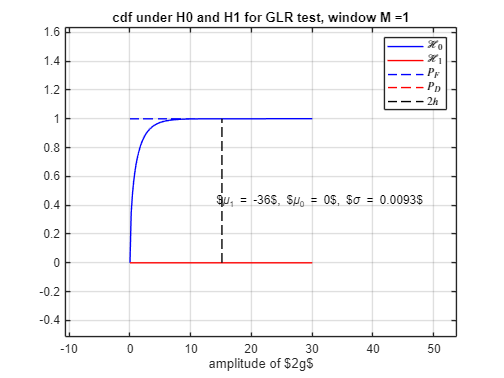

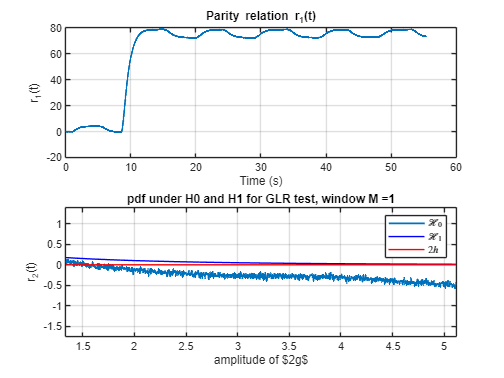




sig_1 = 0.0093;
sig_2 = sig_1;
% sig_3 = sig_2;

sig_matrix = diag([sig_1, sig_2]);

% parameter
J1 = 0.0025;
J2 = 0.0018;
J3 = 0.0018;
k1 = 2.7;
k2 = 2.6;
b1 = 0.0029;
b2 = 0.0002;
b3 = 0.00015;

s = tf('s');

A = [
    0,   0,   0,   1,   0,   0;
    0,   0,   0,   0,   1,   0;
    0,   0,   0,   0,   0,   1;
   -k1/J1,  k1/J1, 0,   -b1/J1, 0,   0;
    k1/J2, -(k1+k2)/J2, k2/J2, 0,   -b2/J2, 0;
    0,   k2/J3, -k2/J3, 0,   0,   -b3/J3
];

B = [0, 0; 0, 0; 0, 0; 1/J1, 0; 0, 1/J2; 0, 0];

C = [1, 0, 0, 0, 0, 0;
     0, 1, 0, 0, 0, 0;
     0, 0, 1, 0, 0, 0];

D = [zeros(3,2)];

Ey = [0; 0; 0];
Ex = [0; 0; 0; 1/J1; 0; 0];

Fx = [B, zeros(6,3)];
Fy = [zeros(3,2), eye(3)];

Qx = lyap(A,B*sig_matrix*B'); % variance of x
Qy = C*Qx*C'+D*sig_matrix*D'; % variance of y

 % Q5.2

% tune h
P_F = 1e-4;
P_M = 1e-2;
f_2 = -0.025;

P_D_req = 1 - P_M;

mu_0 = 0;
mu_1 = dcgain(Gd_r2_y2) * f_2;
mu_delta = mu_1 - mu_0;

h = chi2inv(1-P_F,1)/2;

M = 1;
PD = 0;

while PD < P_D_req
    lambda = M * mu_delta^2 / sig_2^2;
    PD = 1 - ncx2cdf(2*h, 1, lambda);
    M = M + 1;
end

M = M - 1;

lambda = (M* mu_delta^2) / sig_2^2;
P_D = 1 - ncx2cdf(2*h,1,lambda);

GLR_design(M,h,mu_1,mu_0,sig_2)